clc;
close all;
M= 0.5;
m= 0.2;
b= 0.1;
L= 0.3;
J= 0.006;
g= 0.81;
F=0;
theta_d= pi/2;


## Create a FIS object using Mamdani Approach:

%Define a FIS object using the Mamdani Method
my_FIS= mamfis('Name', 'FIS for Inverted pendulum', ...
        'NumInputs',4, 'NumInputMFs', 1, ...
        'NumOutputs', 1, 'NumOutputMFs', 1, ...
        'AddRule', 'none');

    

## Define Input variables and MFs:

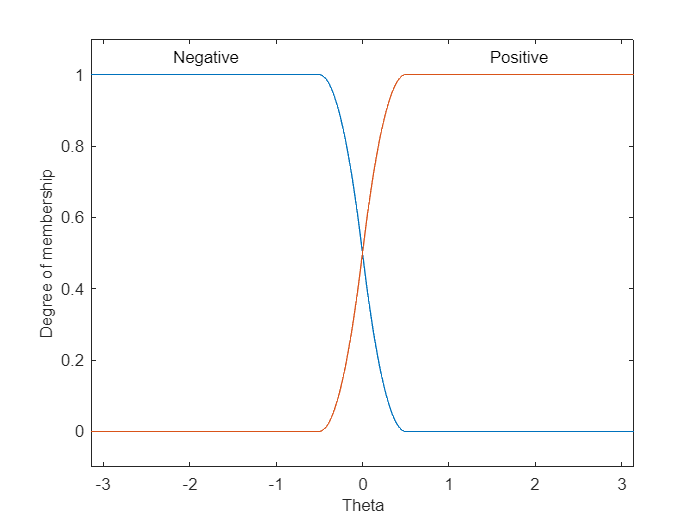

%Define the Input(1)
my_FIS.Inputs(1).Name= 'Theta';
my_FIS.Inputs(1).Range= [-pi pi];
my_FIS.Inputs(1).MembershipFunctions(1).Name= 'Negative';
my_FIS.Inputs(1).MembershipFunctions(1).Type= 'zmf';
my_FIS.Inputs(1).MembershipFunctions(1).Parameters= [-0.5 0.5];
my_FIS.Inputs(1).MembershipFunctions(2).Name= 'Positive';
my_FIS.Inputs(1).MembershipFunctions(2).Type= 'smf';
my_FIS.Inputs(1).MembershipFunctions(2).Parameters= [-0.5 0.5];

%Define the Input(2)
my_FIS.Inputs(2).Name= 'Theta_dot';
my_FIS.Inputs(2).Range= [-5 5];
my_FIS.Inputs(2).MembershipFunctions(1).Name= 'Negative';
my_FIS.Inputs(2).MembershipFunctions(1).Type= 'zmf';
my_FIS.Inputs(2).MembershipFunctions(1).Parameters= [-5 5];
my_FIS.Inputs(2).MembershipFunctions(2).Name= 'Positive';
my_FIS.Inputs(2).MembershipFunctions(2).Type= 'smf';
my_FIS.Inputs(2).MembershipFunctions(2).Parameters= [-5 5];


%Define the Input(3)
my_FIS.Inputs(3).Name= 'x_position';
my_FIS.Inputs(3).Range= [-5 5];
my_FIS.Inputs(3).MembershipFunctions(1).Name= 'Negative';
my_FIS.Inputs(3).MembershipFunctions(1).Type= 'zmf';
my_FIS.Inputs(3).MembershipFunctions(1).Parameters= [-0.1 0.1];
my_FIS.Inputs(3).MembershipFunctions(2).Name= 'Positive';
my_FIS.Inputs(3).MembershipFunctions(2).Type= 'smf';
my_FIS.Inputs(3).MembershipFunctions(2).Parameters= [-0.1 0.1];


%Define the Input(4)
my_FIS.Inputs(4).Name= 'x_velocity';
my_FIS.Inputs(4).Range= [-0.5 0.5];
my_FIS.Inputs(4).MembershipFunctions(1).Name= 'Negative';
my_FIS.Inputs(4).MembershipFunctions(1).Type= 'zmf';
my_FIS.Inputs(4).MembershipFunctions(1).Parameters= [-0.01 0.01];
my_FIS.Inputs(4).MembershipFunctions(2).Name= 'Positive';
my_FIS.Inputs(4).MembershipFunctions(2).Type= 'smf';
my_FIS.Inputs(4).MembershipFunctions(2).Parameters= [-0.01 0.01];

figure;
plotmf(my_FIS, 'input', 1, 1000);

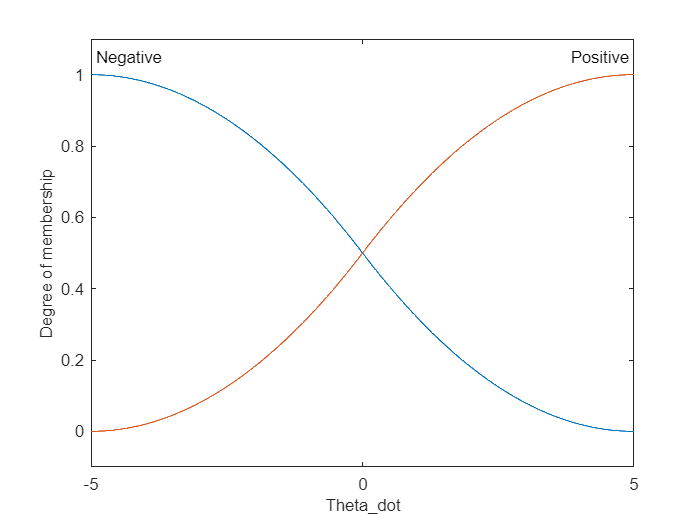

figure;
plotmf(my_FIS, 'input', 2, 1000);

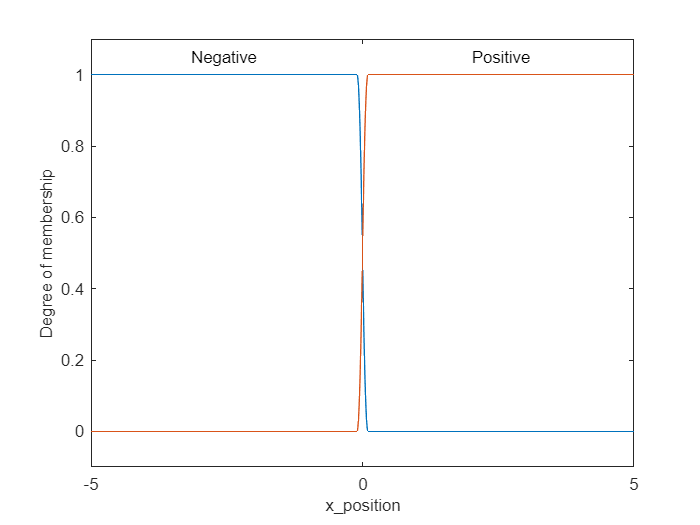

figure;
plotmf(my_FIS, 'input', 3, 1000);

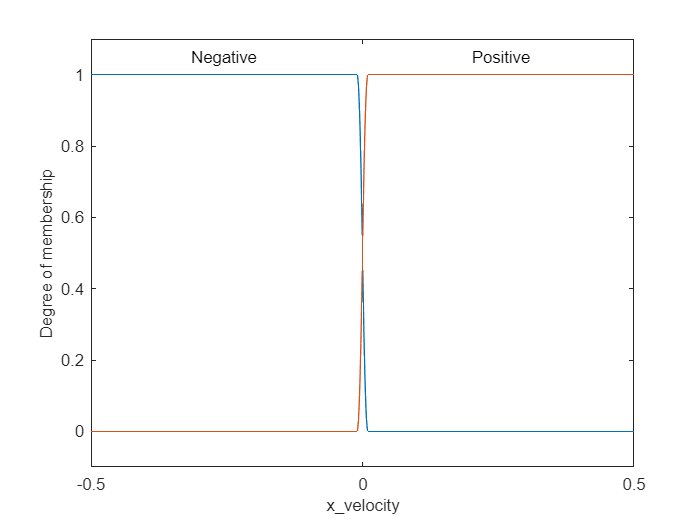

figure;
plotmf(my_FIS, 'input', 4, 1000);

## Define Output Variable and MF:

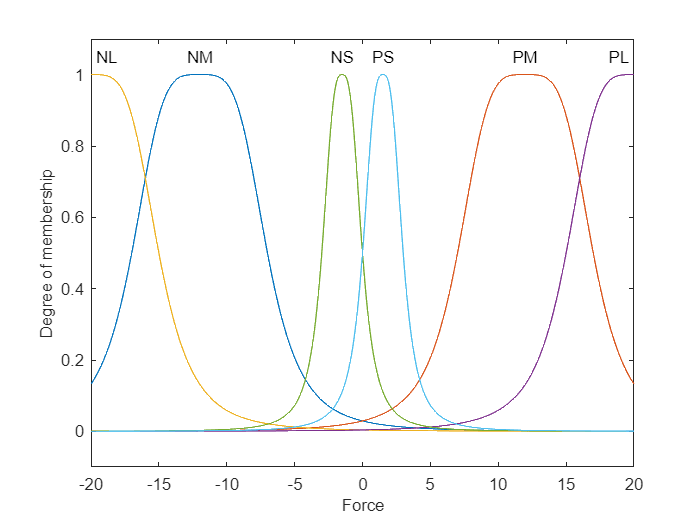


%Define the Output
my_FIS.Outputs(1).Name= 'Force';
my_FIS.Outputs(1).Range= [-20 20];
my_FIS.Outputs(1).MembershipFunctions(1).Name= 'NM';
my_FIS.Outputs(1).MembershipFunctions(1).Type= 'gbellmf';
my_FIS.Outputs(1).MembershipFunctions(1).Parameters= [5, 2, -12];
my_FIS.Outputs(1).MembershipFunctions(2).Name= 'PM';
my_FIS.Outputs(1).MembershipFunctions(2).Type= 'gbellmf';
my_FIS.Outputs(1).MembershipFunctions(2).Parameters= [5, 2, 12];
my_FIS.Outputs(1).MembershipFunctions(3).Name= 'NL';
my_FIS.Outputs(1).MembershipFunctions(3).Type= 'gbellmf';
my_FIS.Outputs(1).MembershipFunctions(3).Parameters= [5, 2, -20];
my_FIS.Outputs(1).MembershipFunctions(4).Name= 'PL';
my_FIS.Outputs(1).MembershipFunctions(4).Type= 'gbellmf';
my_FIS.Outputs(1).MembershipFunctions(4).Parameters= [5, 2, 20];
my_FIS.Outputs(1).MembershipFunctions(5).Name= 'NS';
my_FIS.Outputs(1).MembershipFunctions(5).Type= 'gbellmf';
my_FIS.Outputs(1).MembershipFunctions(5).Parameters= [1.5, 1.5, -1.5];
my_FIS.Outputs(1).MembershipFunctions(6).Name= 'PS';
my_FIS.Outputs(1).MembershipFunctions(6).Type= 'gbellmf';
my_FIS.Outputs(1).MembershipFunctions(6).Parameters= [1.5, 1.5, 1.5];


plotmf(my_FIS, 'output', 1, 1000)

## Fuzzy Inference Engine (Define Rules)


%Inference Engine (Rules)
rules= ["If Theta is Negative then Force is NM",
    "If Theta is Positive then Force is PM",
    "If Theta_dot is Negative then Force is PL",
    "If Theta_dot is Positive then Force is NL",
    "If x_position is Positive then Force is PS",
    "If x_position is Negative then Force is NS",
    "If x_velocity is Positive then Force is PS",
    "If x_velocity is Negative then Force is NS"
   ];
my_FIS= addRule(my_FIS,rules);


## Open in Fuzzy Logic Designer

%fuzzyLogicDesigner(my_FIS)
writeFIS(my_FIS,"IP_FIS.fis");